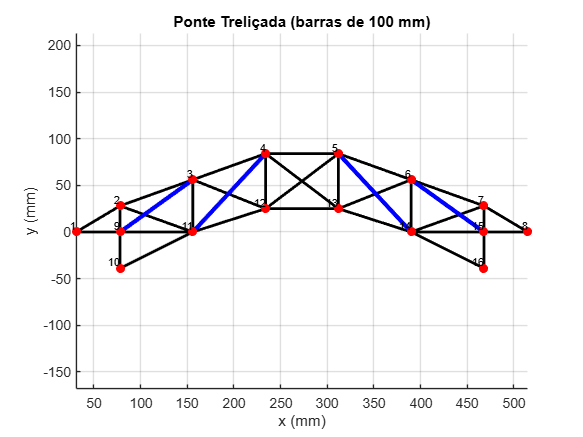

% Coordenadas dos nós da ponte (em mm)
nodes = [
   31   0;    % 1
   78  28;    % 2
  156  56;    % 3
  234  84;    % 4
  312  84;    % 5
  390  56;    % 6
  468  28;    % 7
  515 0;      % 8
  78  0;      %9
  78 -39;     %10
  156 0;      %11
  234 25;     %12
  312 25;     %13
  390  0;     %14
  468 0;      %15
  468 -39;    %16
];


% Matriz de incidências de cada elemento
elementos = [
    1 2; 2 3; 3 4; 4 5; 5 6; 6 7; 7 8; %topo
    2 11; 3 9; 3 12; 4 11; 4 13; 5 12; 5 14; 6 13; 6 15; 7 14; %diagonais
    1 9; 9 11; 11 12; 12 13; 13 14; 14 15; 8 15; % base
    2 9; 3 11; 4 12; 5 13; 6 14; 7 15; % verticais
    9 10; 10 11; 14 16; 15 16; % suporte
];

figure; hold on; axis equal;
for i = 1:size(elementos,1)
    n1 = elementos(i,1);
    n2 = elementos(i,2);
    plot([nodes(n1,1) nodes(n2,1)], [nodes(n1,2) nodes(n2,2)], 'k-', 'LineWidth', 2);
end

% Destacar as barras azuis (sugestão pela imagem)
blue_elementos = [ 3 9; 4 11; 5 14; 6 15];
for i = 1:size(blue_elementos,1)
    n1 = blue_elementos(i,1);
    n2 = blue_elementos(i,2);
    plot([nodes(n1,1) nodes(n2,1)], [nodes(n1,2) nodes(n2,2)], 'b-', 'LineWidth', 3);
end

% Plotar os nós
for i = 1:num_nos
    plot(x_y(i, 1), x_y(i, 2), 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
    text(x_y(i, 1), x_y(i, 2), sprintf(' %d', i), 'FontSize', 8, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
xlabel('x (mm)'); ylabel('y (mm)');
title('Ponte Treliçada (barras de 100 mm)');
grid on;


num_elementos = size(elementos,1);
num_nos = size(nodes,1)

num_nos =     16



% 1c. Propriedades dos elementos (todas iguais para simplificação)
A = 0.02 * 0.003 % área da seção (mm^2)

A =    6.0000e-05


E = 3300 %MPa

E =         3300


%considerando menor tensão
TR_tracao = 55 %  [8000] - 11000(76) MPa

TR_tracao =     55


TR_compressao = 76 % [11000] - 19000(131) MPa

TR_compressao =     76



% 1d. Numeração dos graus de liberdade
n_GL = num_nos * 2;

% 1e. Graus de liberdade restritos (apoios)
% Nós 1,9,10 e 8, 15, 16

fix_dofs = [8*2 - 1, 8*2, 9*2 - 1, 9*2, 15*2-1, 15*2, 1*2 - 1, 1*2, 10*2 - 1, 10*2, 16*2 - 1, 16*2];



%% PASSO 2: Montar a matriz de rigidez de CADA elemento
len_elementos = zeros(num_elementos,1);
cos_sen       = zeros(num_elementos,2);
K_elem        = cell(num_elementos,1);

for e = 1:num_elementos
    n1 = elementos(e,1);
    n2 = elementos(e,2);
    dx = x_y(n2,1)-x_y(n1,1);
    dy = x_y(n2,2)-x_y(n1,2);
    L  = hypot(dx,dy);
    len_elementos(e) = L;
    c = dx/L;  s = dy/L;
    cos_sen(e,:) = [c s];
    ke = (E*A/L)*[ c^2  c*s -c^2 -c*s;
                   c*s  s^2 -c*s -s^2;
                  -c^2 -c*s  c^2  c*s;
                  -c*s -s^2  c*s  s^2 ];
    K_elem{e} = ke;
end

%% PASSO 3: Montar a matriz de rigidez GLOBAL [Kg]
Kg = zeros(n_GL);
for e = 1:num_elementos
    n1 = elementos(e,1);
    n2 = elementos(e,2);
    dofs = [2*n1-1 2*n1 2*n2-1 2*n2];
    Kg(dofs,dofs) = Kg(dofs,dofs) + K_elem{e};
end

disp('==========================================')

Kg

Kg =    6.8839e-03   1.5913e-03  -2.6712e-03  -1.5913e-03            0            0            0            0            0            0            0            0            0            0            0            0  -4.2128e-03            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
   1.5913e-03   9.4803e-04  -1.5913e-03  -9.4803e-04            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
  -2.6712e-03  -1.5913e-03   6.9041e-03   1.5913e-03  -2.1165e-03  -7.5975e-04            0            0            0            0            0            0     


%% PASSO 4: Montar o vetor global de forças [Pg]
Pg = zeros(n_GL,1);
% f) cargas aplicadas: 150 N para baixo distribuídos nos nós 4 e 5
Pg(2*4) = -150;  
Pg(2*5) = -150;

disp('==========================================');

Pg

Pg =      0
     0
     0
     0
     0
     0
     0
  -150
     0
  -150



%% PASSO 5: Aplicar condições de contorno (eliminar linhas/colunas)
% e) 6 apoios do suporte:
%   nó 1 → ux,uy;  nó 9 → ux;  nó 10 → uy;
%   nó 8 → ux,uy;  nó 15 → ux;  nó 16 → uy
restricao = [8*2 - 1, 8*2, 9*2 - 1, 9*2, 15*2-1, 15*2, 1*2 - 1, 1*2, 10*2 - 1, 10*2, 16*2 - 1, 16*2];
restricao

restricao =     15    16    17    18    29    30     1     2    19    20    31    32



Kg_red = Kg;
Pg_red = Pg;
Kg_red(restricao,:) = [];
Kg_red(:,restricao) = [];
Pg_red(restricao)    = [];
disp("==========================================")

Kg_red

Kg_red =    6.9041e-03   1.5913e-03  -2.1165e-03  -7.5975e-04            0            0            0            0            0            0            0            0  -2.1165e-03   7.5975e-04            0            0            0            0            0            0
   1.5913e-03   8.5649e-03  -7.5975e-04  -2.7273e-04            0            0            0            0            0            0            0            0   7.5975e-04  -2.7273e-04            0            0            0            0            0            0
  -2.1165e-03  -7.5975e-04   7.6308e-03   1.6868e-03  -2.1165e-03  -7.5975e-04            0            0            0            0            0            0            0            0  -2.0372e-03   8.0965e-04            0            0            0            0
  -7.5975e-04  -2.7273e-04   1.6868e-03   5.1043e-03  -7.5975e-04  -2.7273e-04            0            0            0            0            0            0            0  -3.5357e-03   8.0965e-04  -3.2179e-04

disp("==========================================")

Pg_red

Pg_red =      0
     0
     0
     0
     0
  -150
     0
  -150
     0
     0



%% PASSO 6: Resolver o sistema de equações
%    [Kg_red] * {U_red} = {Pg_red}
U = Kg_reduzida \ Pg_reduzida;
U_expandida = zeros(num_nos*2, 1);
for row = 1:length(restricao)
    i = restricao(row);
    U_expandida(i) = U(row);
end
disp("==========================================")

U_expandida

U_expandida =   -6.1144e+04
  -5.1736e+05
            0
            0
            0
            0
            0
            0
            0
            0


disp("==========================================")


%% PASSO 7: Determinar deformação e tensão em cada elemento
deformacao = zeros(num_elementos, 1);
tensao = zeros(num_elementos, 1);

for i = 1:num_elementos
    no1 = incidencias(i, 1);
    no2 = incidencias(i, 2);

    nos = [2 * no1 - 1, 2 * no1, 2 * no2 - 1, 2 * no2];

    aux = U_expandida(nos);

    deformacao(i, 1) = (1 / len_elementos(i, 1)) * [-c, -s, c, s] * aux;
    tensao(i, 1) = E * deformacao(i, 1);
end

disp("==========================================")

deformacao

deformacao =   -9.4567e+03
            0
            0
            0
            0
            0
   1.9430e+02
            0
   2.6969e+03
            0


disp("==========================================")

tensao

tensao =   -3.1207e+07
            0
            0
            0
            0
            0
   6.4120e+05
            0
   8.8996e+06
            0


disp("==========================================")

maior_tensao = max(tensao)

maior_tensao =    6.0975e+07


disp("==========================================")


%% PASSO 8: Determinar reações de apoio nos nós com restrição
%   Pg_final = Kg * U  (neste vetor aparecem as reações nos dofs restritos)
disp("==========================================")

Pg_final = Kg * U_expandida

Pg_final =   -1.5900e+03
  -5.8777e+02
   9.8662e+02
   2.4190e+03
   1.4129e+02
   1.0144e+02
            0
            0
            0
            0


disp("==========================================")


%% Projeto Virtual – plot da treliça, elemento crítico e nós restritos
figure; hold on; axis equal; grid on;
title('Projeto Virtual'); xlabel('x [m]'); ylabel('y [m]');

idx_critico = find(tensao == maior_tensao);

% 1) Plota todas as barras: verde, exceto o crítico
for e = 1:num_elementos
    n1 = incidencias(e,1);
    n2 = incidencias(e,2);
    x = [ x_y(n1,1), x_y(n2,1) ];
    y = [ x_y(n1,2), x_y(n2,2) ];
    
    if e == idx_critico
        plot(x, y, 'r-', 'LineWidth', 3);    % crítico em vermelho grosso
    else
        plot(x, y, 'g-', 'LineWidth', 2);    % os demais em verde
    end
end

% 2) Identifica nós restritos
nos_restritos = false(num_nos,1);
for j = 1:length(restricao)
    no = ceil(restricao(j)/2);
    nos_restritos(no) = true;
end

% 3) Plota nós: azuis os restritos, vermelhos os livres
for i = 1:num_nos
    xi = x_y(i,1); 
    yi = x_y(i,2);
    if nos_restritos(i)
        plot(xi, yi, 'o', 'MarkerFaceColor','b', 'MarkerEdgeColor','b', 'MarkerSize',6);
    else
        plot(xi, yi, 'o', 'MarkerFaceColor','r', 'MarkerEdgeColor','r', 'MarkerSize',6);
    end
    text(xi, yi, sprintf(' %d', i), 'FontSize',8, 'VerticalAlignment','bottom','HorizontalAlignment','right');
end

% 4) Anotação do elemento crítico no gráfico
%    localiza o ponto médio da barra crítica para posicionar o texto
n1 = elementos(idx_critico,1);
n2 = elementos(idx_critico,2);
xm = mean([x_y(n1,1), x_y(n2,1)]);
ym = mean([x_y(n1,2), x_y(n2,2)]);
text(xm, ym, sprintf('  %d', idx_critico),'Color','r','FontWeight','bold','FontSize',10);

% Inserir o texto informativo na parte superior esquerda
txt1 = sprintf('Elemento crítico: %d', idx_critico);
disp(txt1);

Elemento crítico: 30


disp('Pintado de VERMELHO no gráfico');

Pintado de VERMELHO no gráfico


disp('Nós restritos estão em AZUL');

Nós restritos estão em AZUL


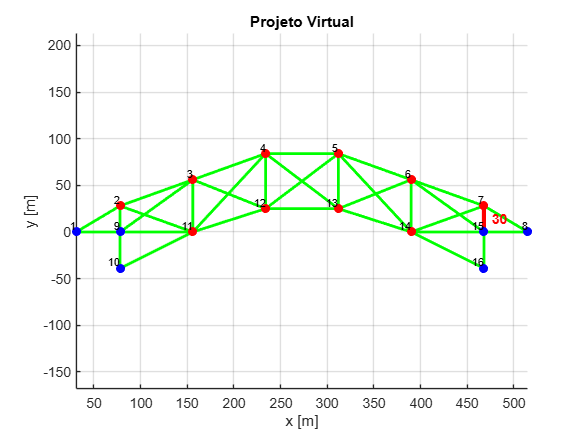


hold off;